# Initializations

clc; clear; close all;

g = 9.81;   % The gravitational acceleration [m/s^2]
l =  0.2;   % Distance from the center of mass to each rotor [m]
m =  0.5;   % Total mass of the quadrotor [kg]
I = [1.24, 1.24, 2.48]; % Mass moment of inertia [kg m^2]
mu = 3.0;   % Maximum thrust of each rotor [N]
sigma = 0.01; % The proportionality constant relating thrust to torque [m]

% Parameter Vector
p = [g l m I mu sigma];


% Initial conditions (State Vector)
z0 = zeros(12,1);   % z is the state vector (?)


r = [0; 0; 0];  % External Forces
n = [0; 0; 0];  % Moment Vector
%u = [1; 0.9; 1.9; 1.5];
u = [1; 0.9; 1.9; 1.5]; % rotor/motor inputs (?)

## Solving the initial-value problem

t = linspace(0, 3, 200);
% quad1 = quadrotor(t, z, u, p, r, n)
% [t,z] = ode45(@(t,z) quad1, t, z0);

[t,z] = ode45(@(t,z) quadrotor(t, z, u, p, r, n), t, z0);

## Plotting the results


$$x^2$$
 
$$\left\lbrack \begin{array}{ccc}
 &  & \\
 &  & \\
 &  & 
\end{array}\right\rbrack$$


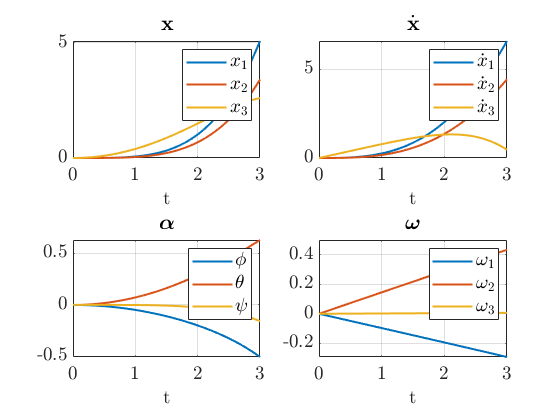

for i=1:4
    ax(i) = subplot(2,2,i,'NextPlot','Add','Box','on','XGrid','on','YGrid','on',...
                'Xlim',[t(1), t(end)],...
                'TickLabelInterpreter','LaTeX','FontSize',14);
    xlabel('t','Interpreter','LaTeX','FontSize',14);        
end


plot(ax(1), t, z(:,1:3), 'LineWidth', 1.5);
legend(ax(1), {'$x_1$', '$x_2$', '$x_3$'},... 
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(1), '${\bf x}$','Interpreter','LaTeX','FontSize',14);
xlabel(ax(1), 't','Interpreter','LaTeX','FontSize',14);

plot(ax(3), t, z(:,4:6), 'LineWidth', 1.5);
legend(ax(3), {'$\phi$', '$\theta$', '$\psi$'},...
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(3), '\boldmath$\alpha$','Interpreter','LaTeX','FontSize',14);

plot(ax(2), t, z(:,7:9), 'LineWidth', 1.5);
legend(ax(2), {'$\dot{x}_1$', '$\dot{x}_2$', '$\dot{x}_3$'},...
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(2), '$\dot{\bf x}$','Interpreter','LaTeX','FontSize',14);

plot(ax(4), t, z(:,10:12), 'LineWidth', 1.5);
legend(ax(4), {'$\omega_1$', '$\omega_2$', '$\omega_3$'},...
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(4), '\boldmath$\omega$','Interpreter','LaTeX','FontSize',14);

## Animation

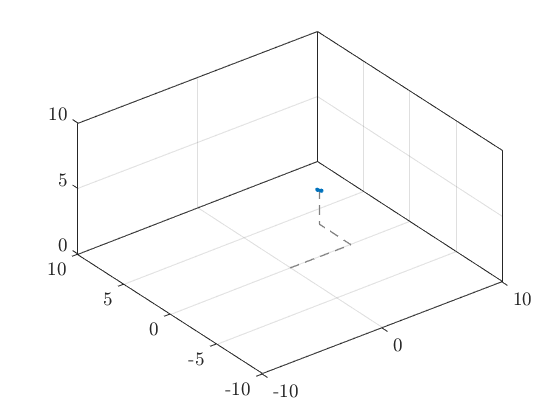

animation_fig = figure;

airspace_box_length = 10;

animation_axes = axes('Parent', animation_fig,...
    'NextPlot','add','DataAspectRatio',[1 1 1],...
    'Xlim',airspace_box_length*[-1.0 1.0],...
    'Ylim',airspace_box_length*[-1.0 1.0],...
    'Zlim',airspace_box_length*[0 1],...
    'box','on','Xgrid','on','Ygrid','on','Zgrid','on',...
    'TickLabelInterpreter','LaTeX','FontSize',14);

view(animation_axes, 3);

N = 10;
Q = linspace(0,2*pi,N)';
circle = 0.3*l*[cos(Q) sin(Q) zeros(N,1)];
loc = l*[1 0 0; 0 1 0; -1 0 0; 0 -1 0];


silhouette = plot3(0,0,0, '--', 'Color', 0.5*[1 1 1], 'LineWidth', 1 ,...
    'Parent', animation_axes);
body = plot3(0,0,0, 'Color',lines(1), 'LineWidth', 2,...
        'Parent', animation_axes);
for i=1:4
    rotor(i) = plot3(0,0,0, 'Color', lines(1), 'LineWidth', 2,...
        'Parent', animation_axes);
end

tic;
for k=1:length(t)
    
    R = [ cos(z(k,5))*cos(z(k,6)), sin(z(k,4))*sin(z(k,5))*cos(z(k,6)) - cos(z(k,4))*sin(z(k,6)), sin(z(k,4))*sin(z(k,6)) + cos(z(k,4))*sin(z(k,5))*cos(z(k,6));
          cos(z(k,5))*sin(z(k,6)), cos(z(k,4))*cos(z(k,6)) + sin(z(k,4))*sin(z(k,5))*sin(z(k,6)), cos(z(k,4))*sin(z(k,5))*sin(z(k,6)) - sin(z(k,4))*cos(z(k,6));
                     -sin(z(k,5)),                                 sin(z(k,4))*cos(z(k,5)),                                 cos(z(k,4))*cos(z(k,5))];
    for i=1:4
%         pose = rotorPositions(quadrotor,z)
        ctr(i,:) = z(k,1:3) + loc(i,:)*R';
        pose = ones(N,1)*z(k,1:3) + (ones(N,1)*loc(i,:) + circle)*R';
        set(rotor(i), 'XData', pose(:,1), 'YData', pose(:,2),  'ZData', pose(:,3) );
         
    end
    set(silhouette,'XData', [0, z(k,1), z(k,1), z(k,1)],...
        'YData', [0, 0, z(k,2), z(k,2)],...
        'ZData', [0, 0, 0, z(k,3)]);
    set(body, 'XData', [ctr([1 3],1); NaN; ctr([2 4],1)], ...
        'YData', [ctr([1 3],2); NaN; ctr([2 4],2)],...
        'ZData', [ctr([1 3],3); NaN; ctr([2 4],3)] );
    pause(t(k)-toc);
    pause(0.01);
end